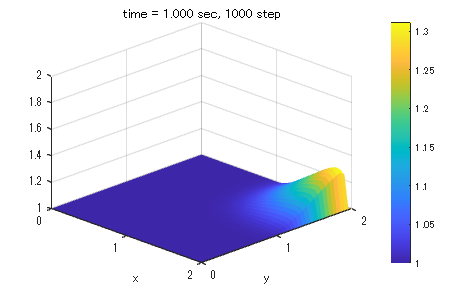

% 条件設定
nx = 41;
ny = 41;
nt = 1000;
c = 1;
dx = 2 / (nx - 1);
dy = 2 / (ny - 1);
sigma = 0.004;
nu = 0.01;
dt = sigma * dx * dy / nu;

x = linspace(0, 2, nx);
y = linspace(0, 2, ny);

uinit = 2;
vinit = uinit;

% 初期状態の設定
u = ones(ny, nx);
v = ones(ny, nx);
u(round(0.5 / dy):round(1 / dy), round(0.5 / dx):round(1 / dx)) = uinit;
v(round(0.5 / dy):round(1 / dy), round(0.5 / dx):round(1 / dx)) = vinit;

% アニメーションを作成するFuncAnimationオブジェクト
figure('Position', [100, 100, 800, 500]);
ax = gca;
[X, Y] = meshgrid(x, y);
surf = surf(ax, X, Y, u, 'EdgeColor', 'none');
colormap(ax, 'parula'); % 'parula'カラーマップを使用
colorbar(ax);
xlabel(ax, 'x');
ylabel(ax, 'y');
zlim(ax, [1, uinit]);
title(ax, ['time = ', num2str(0, '%.3f'), ' sec, 0 step']);
view(ax, [45, 30]);

for i = 1:nt
    [u, v] = diffuse(u, v, dt, dx, dy, nu);
    set(surf, 'ZData', u);
    title(ax, ['time = ', num2str(i*dt, '%.3f'), ' sec, ', num2str(i), ' step']);
    drawnow;
end

function [u, v] = diffuse(un, vn, dt, dx, dy, nu)
    u = un;
    v = vn;
    u(2:end-1, 2:end-1) = (un(2:end-1, 2:end-1) - ...
                         dt / dx * un(2:end-1, 2:end-1) .* ...
                         (un(2:end-1, 2:end-1) - un(2:end-1, 1:end-2)) - ...
                         dt / dy * vn(2:end-1, 2:end-1) .* ...
                         (un(2:end-1, 2:end-1) - un(1:end-2, 2:end-1)) + ...
                         nu * dt / dx^2 * ...
                         (un(2:end-1, 3:end) - 2 * un(2:end-1, 2:end-1) + un(2:end-1, 1:end-2)) + ...
                         nu * dt / dy^2 * ...
                         (un(3:end, 2:end-1) - 2 * un(2:end-1, 2:end-1) + un(1:end-2, 2:end-1)));
    v(2:end-1, 2:end-1) = (vn(2:end-1, 2:end-1) - ...
                         dt / dx * un(2:end-1, 2:end-1) .* ...
                         (vn(2:end-1, 2:end-1) - vn(2:end-1, 1:end-2)) - ...
                         dt / dy * vn(2:end-1, 2:end-1) .* ...
                         (vn(2:end-1, 2:end-1) - vn(1:end-2, 2:end-1)) + ...
                         nu * dt / dx^2 * ...
                         (vn(2:end-1, 3:end) - 2 * vn(2:end-1, 2:end-1) + vn(2:end-1, 1:end-2)) + ...
                         nu * dt / dy^2 * ...
                         (vn(3:end, 2:end-1) - 2 * vn(2:end-1, 2:end-1) + vn(1:end-2, 2:end-1)));
    u(1, :) = 1;
    u(end, :) = 1;
    u(:, 1) = 1;
    u(:, end) = 1;
    v(1, :) = 1;
    v(end, :) = 1;
    v(:, 1) = 1;
    v(:, end) = 1;
end
